## Lab 4 Report: Modelling Transfer Function of second-order Mass-Spring-Damper System.

Name:

ID:

### Task 1

#### Underdamped

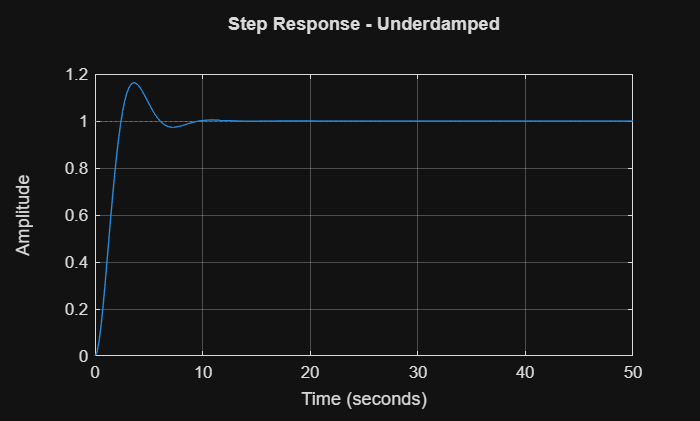

% define timestep, k, m
% s = tf('s')

% Underdamped: choose b such that the damping ratio (zeta) is within 0 and 1.
% system_underdamped = equation 14
% use step(system_underdamped, timestep); to plot step response

timestep = 50;
k = 1;
m = 1;
s = tf('s');

b_underdamped = 1;

system_underdamped = 1/(m*s^2+b_underdamped*s+k);
step(system_underdamped, timestep)
title('Step Response - Underdamped');
grid on;

#### Overdamped

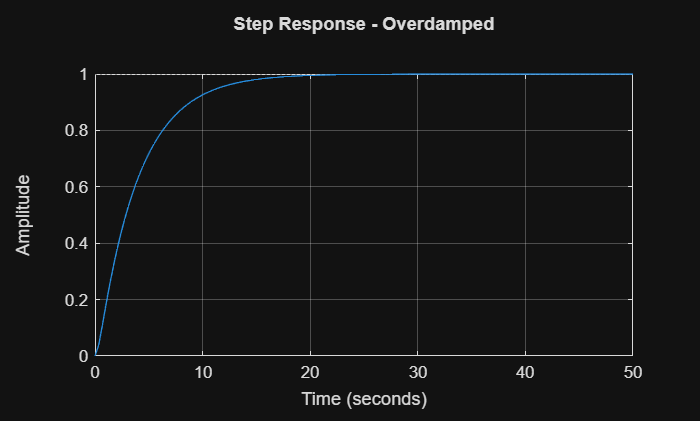

% Overdamped: choose b such that the damping ratio (zeta) is larger than 1.
% system_overdamped = equation 14
% use step(system_overdamped, timestep); to plot step response

b_overdamped = 4;

system_overdamped = 1/(m*s^2+b_overdamped*s+k);
step(system_overdamped, timestep)
title('Step Response - Overdamped');
grid on;

#### Critically Damped

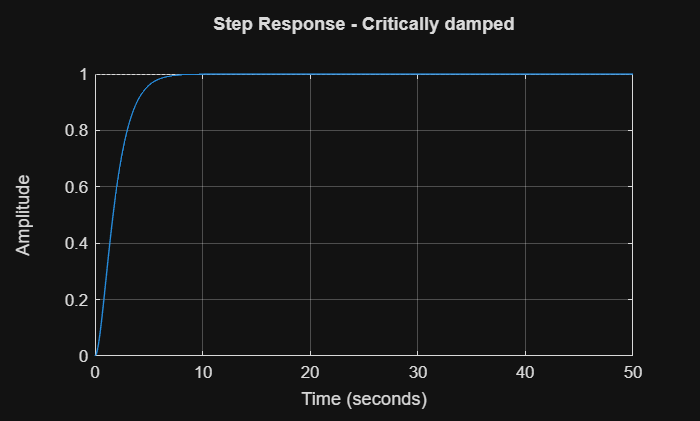

% Critically damped: choose b such that the damping ratio (zeta) equals 1.
% system_criticallyDamped = equation 14
% use step(system_criticallyDamped, timestep); to plot step response

b_criticallyDamped = 2;

system_criticallyDamped = 1/(m*s^2+b_criticallyDamped*s+k);
step(system_criticallyDamped, timestep)
title('Step Response - Critically damped');
grid on;

#### Undamped

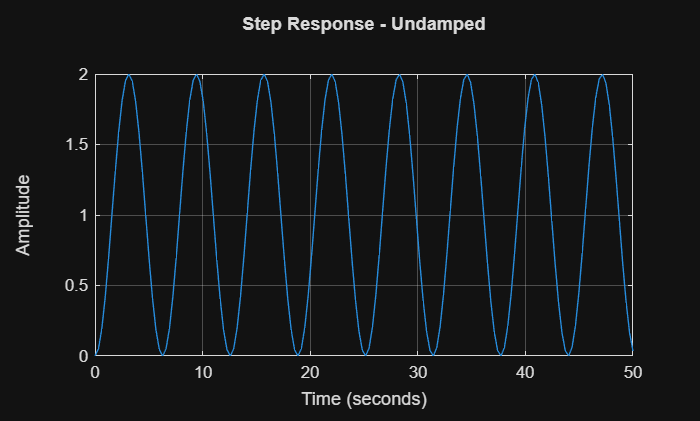

% Undamped: choose b such that the damping ratio (zeta) is 0.
% system_undamped = equation 14
% use step(system_undamped, timestep); to plot step response

b_undamped = 0;

system_undamped = 1/(m*s^2+b_undamped*s+k);
step(system_undamped, timestep)
title('Step Response - Undamped');
grid on;

#### Function for pole-zero plot

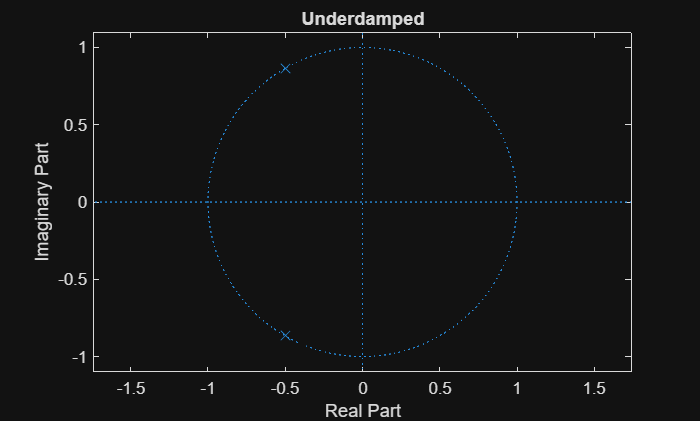

% Define a function that takes transfer function parameters (numerator,
% denominator), returns poles-zeros, and finally generates a pole-zero map.

% Defining function
% function functionName(input_parameter1, input_parameter2,...)
    % You can use tf2zp for getting pole-zero-gain from transfer function numerator and denominator
    % You can use zplane for plotting pole-zero map from pole-zero values
% end

% Once you define your function, move it to the bottom section 'Functions' of this live script

% Example: a function tfTopzPlot(1, [1 2 1]) takes transfer function
% numerator and denominator 1(where b=2) and generates a pole-zero map.

function tfTopzMap(numerator, denominator, ttl)
    [z,p,k] = tf2zp(numerator,denominator);
    zplane(z,p)
    title(ttl);
end

tfTopzMap(1, [1 1 1], 'Underdamped')

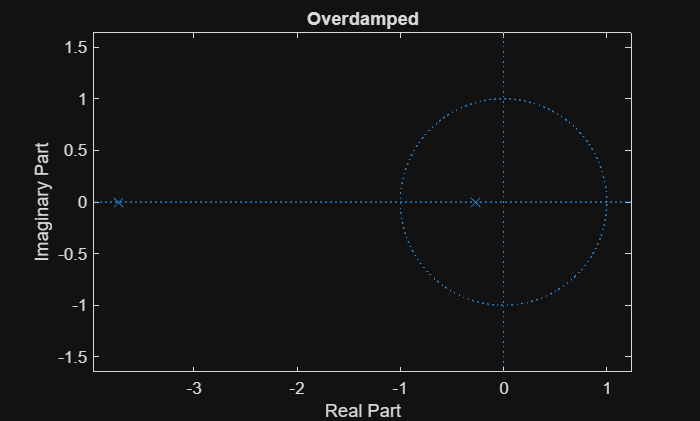

tfTopzMap(1, [1 4 1], 'Overdamped') 

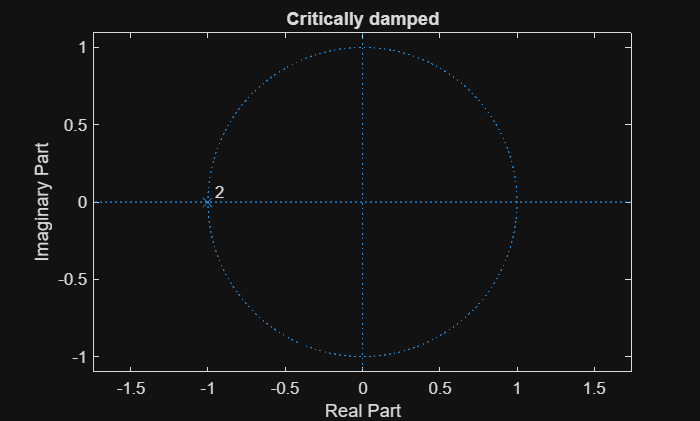

tfTopzMap(1, [1 2 1], 'Critically damped')

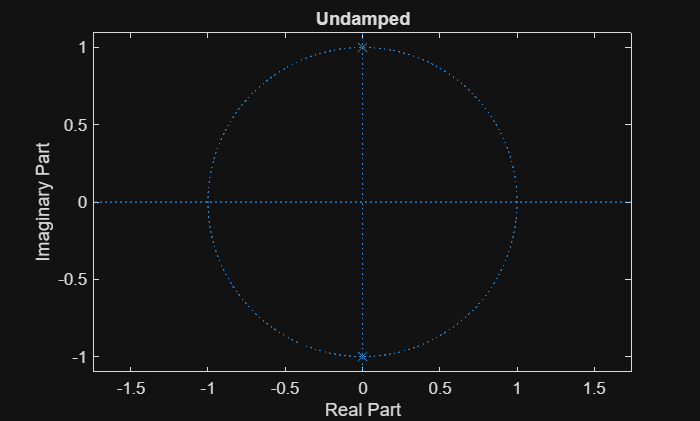

tfTopzMap(1, [1 0 1], 'Undamped')

#### Determine



%zeta = equation 5
% w_n = equation 6
% tp = time to reach first peak: t(y == max(y)), where [y t] =
% step(sys_under, 50)
% 1% settling time ts using equation 9
% 10-90% rise time tr using equation 10
% percent overshoot Mp using equation 8

zeta = b_underdamped/(2*sqrt(k*m))

zeta = 0.5000

w_n = sqrt(k/m)

w_n = 1

[y, t] = step(system_underdamped, timestep);
tp = t(y == max(y))  % Find peak time

tp = 3.6900

ts = 4.6/(zeta*w_n)  % Settling time

ts = 9.2000

tr = 1.8/w_n         % Rise time

tr = 1.8000

Mp = exp(-zeta*pi/sqrt(1-zeta^2))  % Percent overshoot

Mp = 0.1630

### Task 2

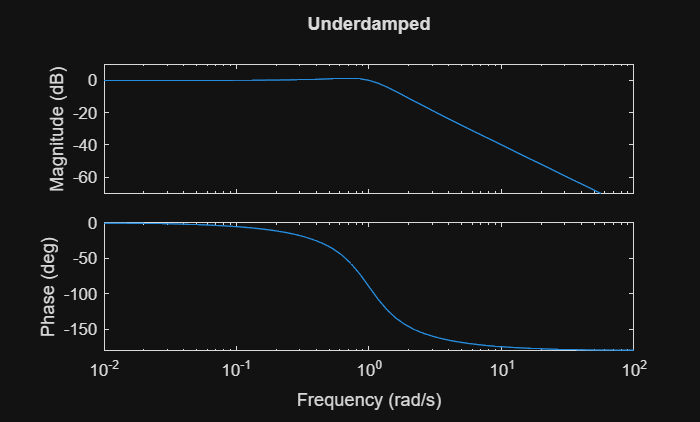

% function plotBode(system)
    % you can use bode(system) for printing bode plot - you'll need Signal Processing Toolbox addon
% end

function plotBode(system, ttl)
    bode(system)
    title(ttl);
end

% example usage
plotBode(system_underdamped, 'Underdamped')

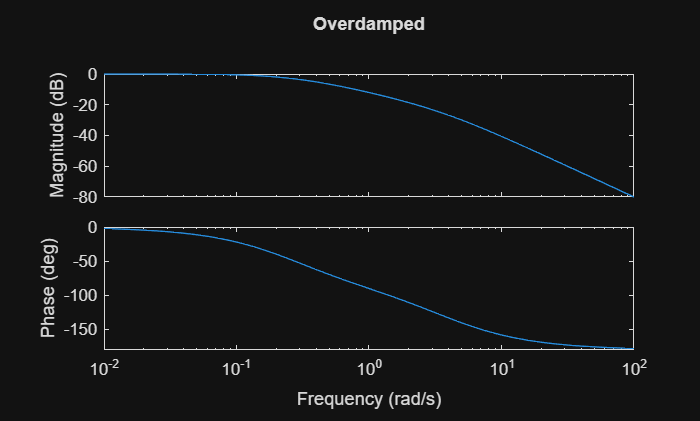

plotBode(system_overdamped, 'Overdamped')

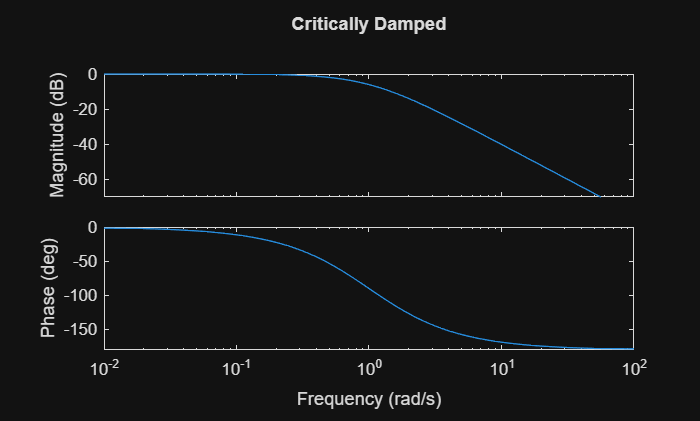

plotBode(system_criticallyDamped, 'Critically Damped')

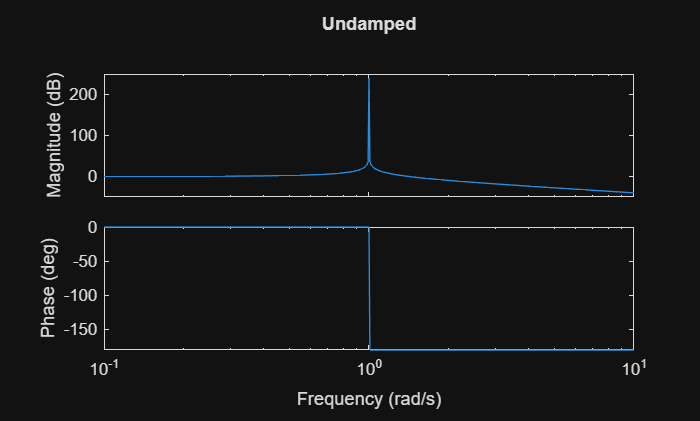

plotBode(system_undamped, 'Undamped')

### Task 3

Q = 1/(2*zeta)

Q = 1

w_n

w_n = 1

### Post Lab

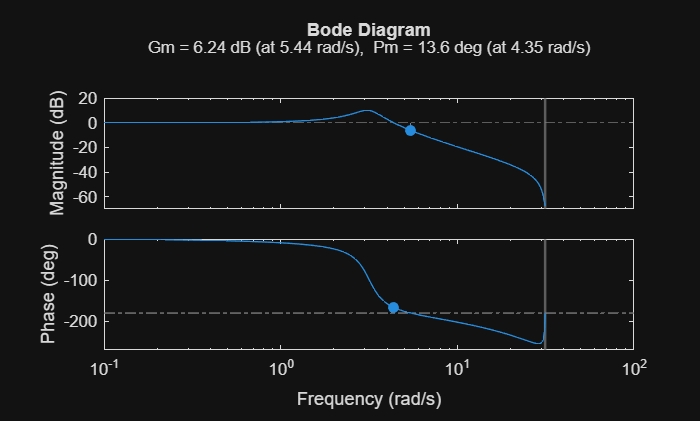

% Create the tf system
gs = tf([0.04798 0.0464],[1 -1.81 0.9048],0.1); % Sampling time is 0.1

% Plot the gain margin (GM) and phase margin (PM)
[Gm,Pm,Wcg,Wcp] = margin(gs);

% Plot GM and PM
margin(gs);

### Functions

% Move your functions below
